# Bootstrpped Switches

clear
clc

## Design Specification

N = 17;                                                 % number of bit 
F_s = 5e6;                                              % sample rate 
T_ck = 1 / F_s;                                         % period
T_track = T_ck / 2;

A = 0.895;                                              % input range
Vref = 1.8;                                             % reference voltage
SINAD_max = 6.02*N + 1.76                      

SINAD_max = 104.1000

### Thermal Noise of Sample

penalty_Noise = -1;                                     % -1dB penalty due to kT/C noise              
LSB = Vref / 2^N;                                       % Least Significant Bit
T = 348;                                                % T = 75°C = 348K
kB = 1.38e-23;                                          % Boltzmann constant

% [cap_sample, sinad_noise] = cal_SampleCap(A, LSB, penalty_Noise, T)
% 电容值太大了，按照-1dB的计算难以实现，按照以往的设计38.72pF;
cap_sample = 38.75e-12;
Noise_Q = LSB^2 / 12

Noise_Q = 1.5716e-11

Noise_T = kB*T/cap_sample

Noise_T = 1.2393e-10

sinad = mag2db((A^2/2) / (Noise_T+Noise_Q)) / 2

sinad = 94.5758

### Track-Mode Distortion

THD = -SINAD_max -3;
win_max = 2*pi*(F_s/2);

delta_Ron = db2mag(THD) / (win_max*cap_sample) 

delta_Ron = 0.0073

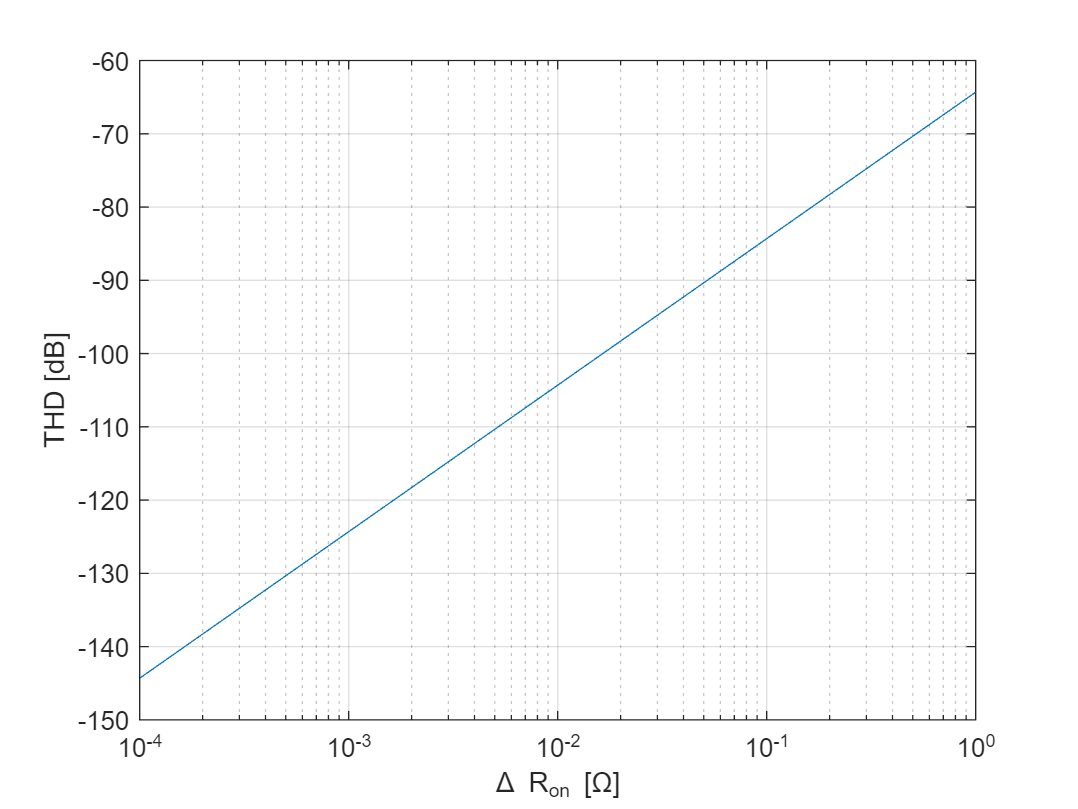

delta_ron = logspace(0, -4, 20);
thd = mag2db(win_max*cap_sample.*delta_ron);
figure()
semilogx(delta_ron, thd);
grid on; box on;
xlabel("\Delta R_{on} [\Omega]");
ylabel("THD [dB]")

% 取delta Ron = 0.01;
Delta_Ron = 0.01

Delta_Ron = 0.0100

THD_DRon = mag2db(win_max*cap_sample*Delta_Ron)

THD_DRon = -104.3122

### Low-Pass Filter 

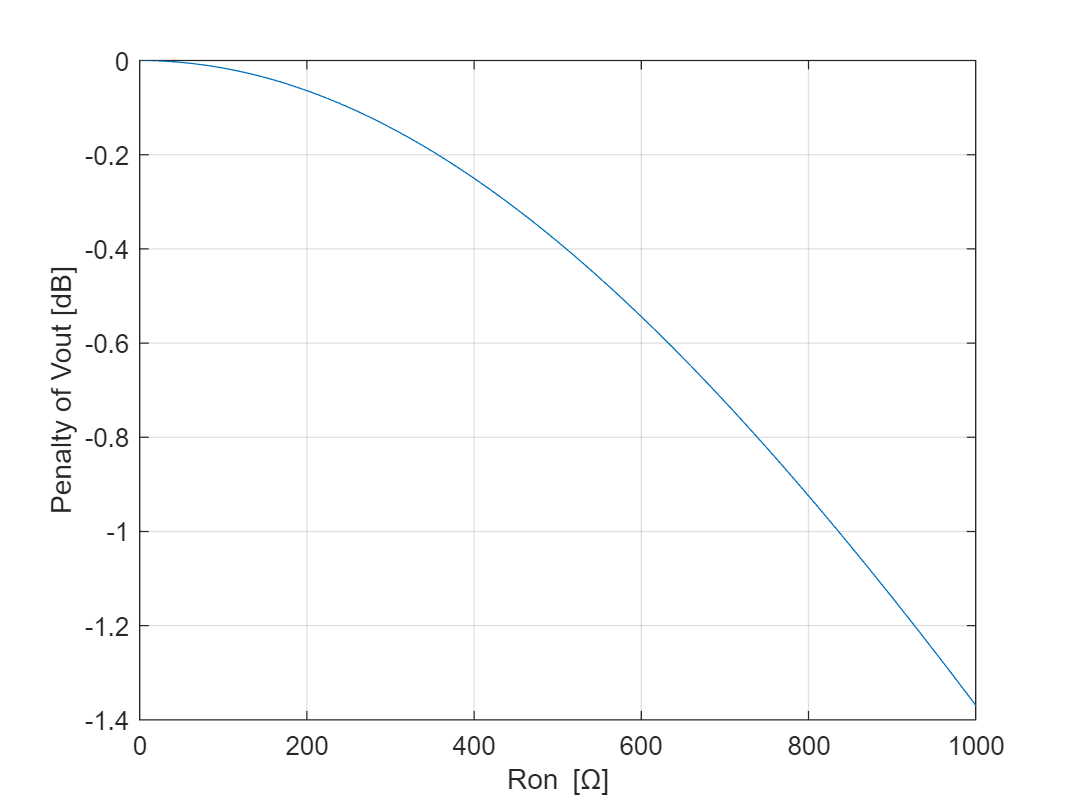

% 考虑到电容电阻的低通效应
ron = logspace(0, 3, 200);
penalty_A = mag2db(1./sqrt(1+ron.^2.*cap_sample^2*win_max^2));
figure()
plot(ron, penalty_A);
grid on; box on;
xlabel("Ron [\Omega]");
ylabel("Penalty of Vout [dB]");

% 导通电阻的低通效应影响很小，几乎不用考虑；

function [cap, sinad] = cal_SampleCap(A, LSB, penalty, T)
    if (nargin < 4)
        T = 348;                                    % default temperture    
    end
    kB = 1.38e-23;                                  % Boltzmann constant
    Noise_Q = LSB^2 / 12;
    Noise_T = (Noise_Q*(1-db2mag(2*penalty)))/db2mag(2*penalty);
    cap = 2*kB*T / Noise_T;
    sinad = mag2db((A^2/2)/(Noise_Q + Noise_T))/2;
end